output_filename = '/Users/telegramsam/Desktop/genomics/final_coursework/';

# Task 1

min_orf_length = 70;

seq_orca = getgenbank('NC_023889','sequenceonly','true');

% Length and base count of the sequence:
whos seq_orca

  Name          Size               Bytes  Class    Attributes

  seq_orca      1x16386            32772  char               



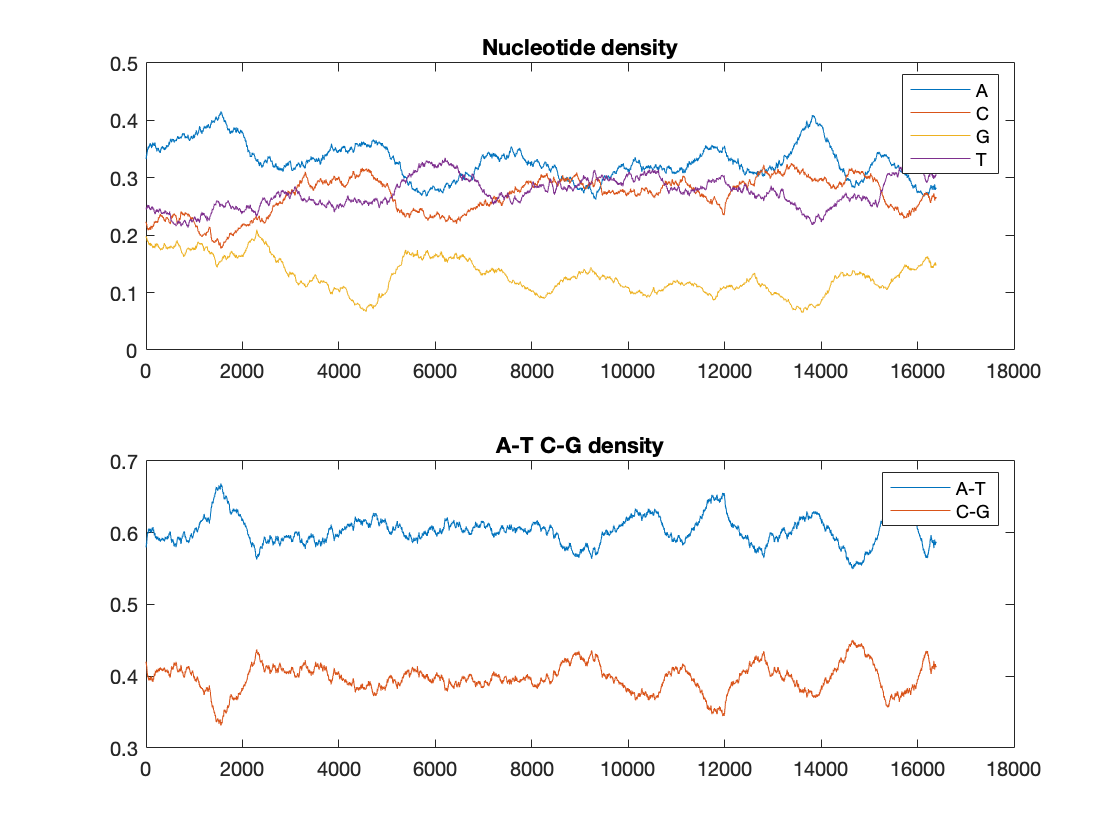

ntdensity(seq_orca)

% Dimers frequency:
[dimers, dimer_matrix] = dimercount(seq_orca);
dimer_matrix

dimer_matrix =     0.1065    0.0861    0.0499    0.0862
    0.0846    0.0790    0.0206    0.0841
    0.0400    0.0350    0.0243    0.0292
    0.0975    0.0684    0.0336    0.0749


basecount(seq_orca)

ans = struct with fields:
    A: 5384
    C: 4399
    G: 2106
    T: 4496



% Codon count:
codoncount(seq_orca)

AAA - 211     AAC - 164     AAG -  86     AAT - 208     
ACA - 127     ACC - 127     ACG -  43     ACT - 188     
AGA -  75     AGC - 138     AGG - 101     AGT -  74     
ATA - 119     ATC - 103     ATG -  71     ATT - 146     
CAA - 140     CAC - 140     CAG -  60     CAT - 150     
CCA - 103     CCC - 139     CCG -  44     CCT - 188     
CGA -  28     CGC -  40     CGG -  32     CGT -  41     
CTA -  95     CTC - 102     CTG -  48     CTT - 122     
GAA -  53     GAC -  50     GAG -  26     GAT -  35     
GCA -  27     GCC -  41     GCG -   5     GCT -  51     
GGA -  19     GGC -  28     GGG -  17     GGT -  24     
GTA -  42     GTC -  25     GTG -  18     GTT -  32     
TAA - 179     TAC - 153     TAG -  96     TAT - 166     
TCA - 103     TCC - 100     TCG -  32     TCT - 121     
TGA -  58     TGC -  46     TGG -  61     TGT -  53     
TTA - 107     TTC -  91     TTG -  38     TTT - 111     



% Detecting ORFS:

% Average ORF length of permuted genome:

% Null hypothesis: orf lengths for the orca are distributed identically as
% for random permutations of the genome
% Alternative hypothesis: orfs are longer for the orca

n_perms = 100;

ORF_lengths_perm = [];

pb = waitbar(0, 'Starting');
for perm_num = 1:n_perms
    seq_perm = seq_orca(randperm(length(seq_orca)));
    ORFs_perm = seqshoworfs(seq_perm, 'MinimumLength', 1, 'nodisplay','true', ...
        'GeneticCode', 2, 'frames', 'all');
    for frame = 1:6
        start = ORFs_perm(frame).Start;
        stop = ORFs_perm(frame).Stop;
        start = start(1:length(stop));
        
        ORF_lengths_perm = [ORF_lengths_perm; (stop - start)'];
    end
    progress = perm_num/n_perms;
    waitbar(progress, pb, sprintf('Progress: %d %%', floor(progress*100)));
end
close(pb);

% Critical region for ORFs significantly longer than ORFs from random perm
% at significance level given by:
sig_level = 0.01;
critical_value = prctile(ORF_lengths_perm, 100*(1-sig_level))

critical_value = 186


% ORF lengths for orca:

ORFs_orca = seqshoworfs(seq_orca, 'MinimumLength', critical_value, ...
    'nodisplay','true', 'GeneticCode', 2, 'frames', 'all');
ORF_lengths_orca = [];

for frame = 1:6
    start = ORFs_orca(frame).Start;
    stop = ORFs_orca(frame).Stop;
    start = start(1:length(stop));
    
    ORF_lengths_orca = [ORF_lengths_orca; (stop - start)'];
end

% Of those how many are in the critical region?
length(ORF_lengths_orca)

ans = 9

% the shortest of which has length
min(ORF_lengths_orca)

ans = 678

% Finding the CYTB and CYTC

CYTB_orca_NT = seq_orca(14192:15331);
CYTB_orca_AA = nt2aa(CYTB_orca_NT, 'ACGTOnly', 'false');
COX1_orca_NT = seq_orca(5360:6910);
COX1_orca_AA = nt2aa(COX1_orca_NT, 'ACGTOnly', 'false');

# Task 3

% Importing the CYTB and CYTC (COX1) for the other dolphin species

% Stenella longirostris:
seq_dolphin1 = getgenbank('NC_032301','sequenceonly','true');
CYTB_dolphin1_NT = seq_dolphin1(14185:15324);
COX1_dolphin1_NT = seq_dolphin1(5353:6903);

% Lagenorhynchus obliquidens
seq_dolphin2 = getgenbank('MH992390','sequenceonly','true');
CYTB_dolphin2_NT = seq_dolphin2(14198:15337);
COX1_dolphin2_NT = seq_dolphin2(5365:6915);

% Lagenorhynchus obscurus
CYTB_dolphin3_NT = getgenbank('AY821653','sequenceonly','true');
% COX1 unavailable for this species

% Tursiops truncatus
seq_dolphin4 = getgenbank('MF669486','sequenceonly','true');
CYTB_dolphin4_NT = seq_dolphin4(14195:15334);
COX1_dolphin4_NT = seq_dolphin4(5363:6913);

%Delphinus delphis
seq_dolphin5 = getgenbank('MH000365','sequenceonly','true');
CYTB_dolphin5_NT = seq_dolphin5(14195:15334);
COX1_dolphin5_NT = seq_dolphin5(5363:6913);

%Physeter catodon
seq_whale = getgenbank('KU891394','sequenceonly','true');
CYTB_whale_NT = seq_whale(14201:15340);
% COX1 unavailable for this species

dolphins_struct.CYTB = {CYTB_orca_NT, CYTB_dolphin1_NT, CYTB_dolphin2_NT, ...
                        CYTB_dolphin3_NT, CYTB_dolphin4_NT, CYTB_dolphin5_NT, CYTB_whale_NT};
dolphins_struct.Names = {'Orcinus orca', 'Stenella longirostris', 'Lagenorhynchus obliquidens', ...
                        'Lagenorhynchus obscurus', 'Tursiops truncatus', 'Delphinus delphis', 'Physeter catodon'};

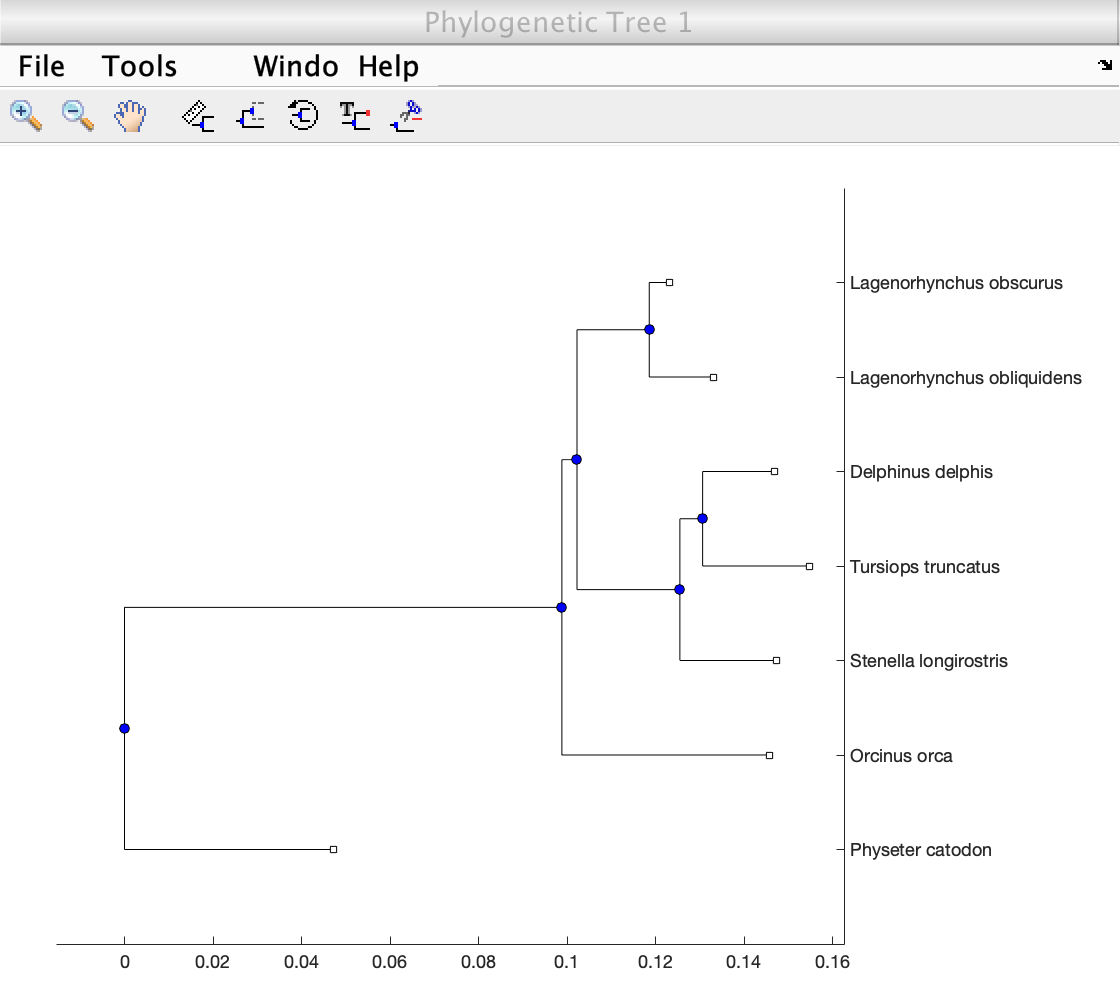

distance_matrix = squareform(seqpdist(dolphins_struct.CYTB, 'method',...
    'jukes-cantor','indels','pair'));
tree = seqneighjoin(distance_matrix, 'equivar',dolphins_struct.Names);
tree = reroot(tree, 7);
phytreeviewer(tree)

# Task 4

% Balaenoptera musculus
seq_bluewhale = getgenbank('MF409242','sequenceonly','true');
CYTB_bluewhale_NT = seq_bluewhale(14190:15329);
COX1_bluewhale_NT = seq_bluewhale(5359:6909);

% Monodon monoceros 
seq_narwhal = getgenbank('MT251289','sequenceonly','true');
CYTB_narwhal_NT = seq_narwhal(14193:15332);
COX1_narwhal_NT = seq_narwhal(5364:6914);

% Delphinapterus leucas
seq_beluga = getgenbank('KY444734','sequenceonly','true');
CYTB_beluga_NT = seq_beluga(14193:15332);
COX1_beluga_NT = seq_beluga(5365:6915);

% Odobenus rosmarus rosmarus
seq_walrus = getgenbank('MK671141','sequenceonly','true');
CYTB_walrus_NT = seq_walrus(14170:15309);
COX1_walrus_NT = seq_walrus(5347:6891);

species_struct.Names = {'Orcinus orca', 'Stenella longirostris', 'Lagenorhynchus obliquidens', ...
                        'Tursiops truncatus', 'Delphinus delphis', 'Balaenoptera musculus',...
                        'Monodon monoceros', 'Delphinapterus leucas', 'Odobenus rosmarus'};
species_struct.CYTB_NT = {CYTB_orca_NT, CYTB_dolphin1_NT, CYTB_dolphin2_NT, CYTB_dolphin4_NT,...
                       CYTB_dolphin5_NT, CYTB_bluewhale_NT, CYTB_narwhal_NT, CYTB_beluga_NT...
                       CYTB_walrus_NT};
species_struct.COX1_NT = {COX1_orca_NT, COX1_dolphin1_NT, COX1_dolphin2_NT, COX1_dolphin4_NT,...
                       COX1_dolphin5_NT, COX1_bluewhale_NT, COX1_narwhal_NT, COX1_beluga_NT...
                       COX1_walrus_NT};

n_species = length(species_struct.Names);
outgroup_num = n_species; % will keep the outgroup at the end of the list.

% Translate to amino acids
for s = 1:n_species
    species_struct.CYTB_AA{s} = nt2aa(species_struct.CYTB_NT{s}, 'ACGTOnly', 'false');
    species_struct.COX1_AA{s} = nt2aa(species_struct.COX1_NT{s}, 'ACGTOnly', 'false');
end

% Compute pairwise distances between CYTB of each species and plot distances, and the same for COX1:

CYTB_NT_dist_matrix = squareform(seqpdist(species_struct.CYTB_NT, 'method', 'jukes-cantor'))

CYTB_NT_dist_matrix =          0    0.0969    0.0796    0.1057    0.0930    0.1886    0.1396    0.1406    0.2889
    0.0969         0    0.0777    0.0486    0.0458    0.1748    0.1386    0.1498    0.2830
    0.0796    0.0777         0    0.0853    0.0767    0.1706    0.1185    0.1315    0.2771
    0.1057    0.0486    0.0853         0    0.0403    0.1664    0.1325    0.1529    0.2783
    0.0930    0.0458    0.0767    0.0403         0    0.1748    0.1376    0.1498    0.2830
    0.1886    0.1748    0.1706    0.1664    0.1748         0    0.1801    0.1737    0.2678
    0.1396    0.1386    0.1185    0.1325    0.1376    0.1801         0    0.0720    0.2818
    0.1406    0.1498    0.1315    0.1529    0.1498    0.1737    0.0720         0    0.3033
    0.2889    0.2830    0.2771    0.2783    0.2830    0.2678    0.2818    0.3033         0


COX1_NT_dist_matrix = squareform(seqpdist(species_struct.COX1_NT, 'method', 'jukes-cantor'))

COX1_NT_dist_matrix =          0    0.0786    0.0675    0.0779    0.0654    0.1634    0.1326    0.1415    0.2730
    0.0786         0    0.0612    0.0321    0.0248    0.1689    0.1319    0.1326    0.2549
    0.0675    0.0612         0    0.0626    0.0537    0.1582    0.1266    0.1326    0.2647
    0.0779    0.0321    0.0626         0    0.0242    0.1582    0.1312    0.1438    0.2617
    0.0654    0.0248    0.0537    0.0242         0    0.1605    0.1275    0.1356    0.2583
    0.1634    0.1689    0.1582    0.1582    0.1605         0    0.1620    0.1674    0.2647
    0.1326    0.1319    0.1266    0.1312    0.1275    0.1620         0    0.0702    0.2625
    0.1415    0.1326    0.1326    0.1438    0.1356    0.1674    0.0702         0    0.2598
    0.2730    0.2549    0.2647    0.2617    0.2583    0.2647    0.2625    0.2598         0


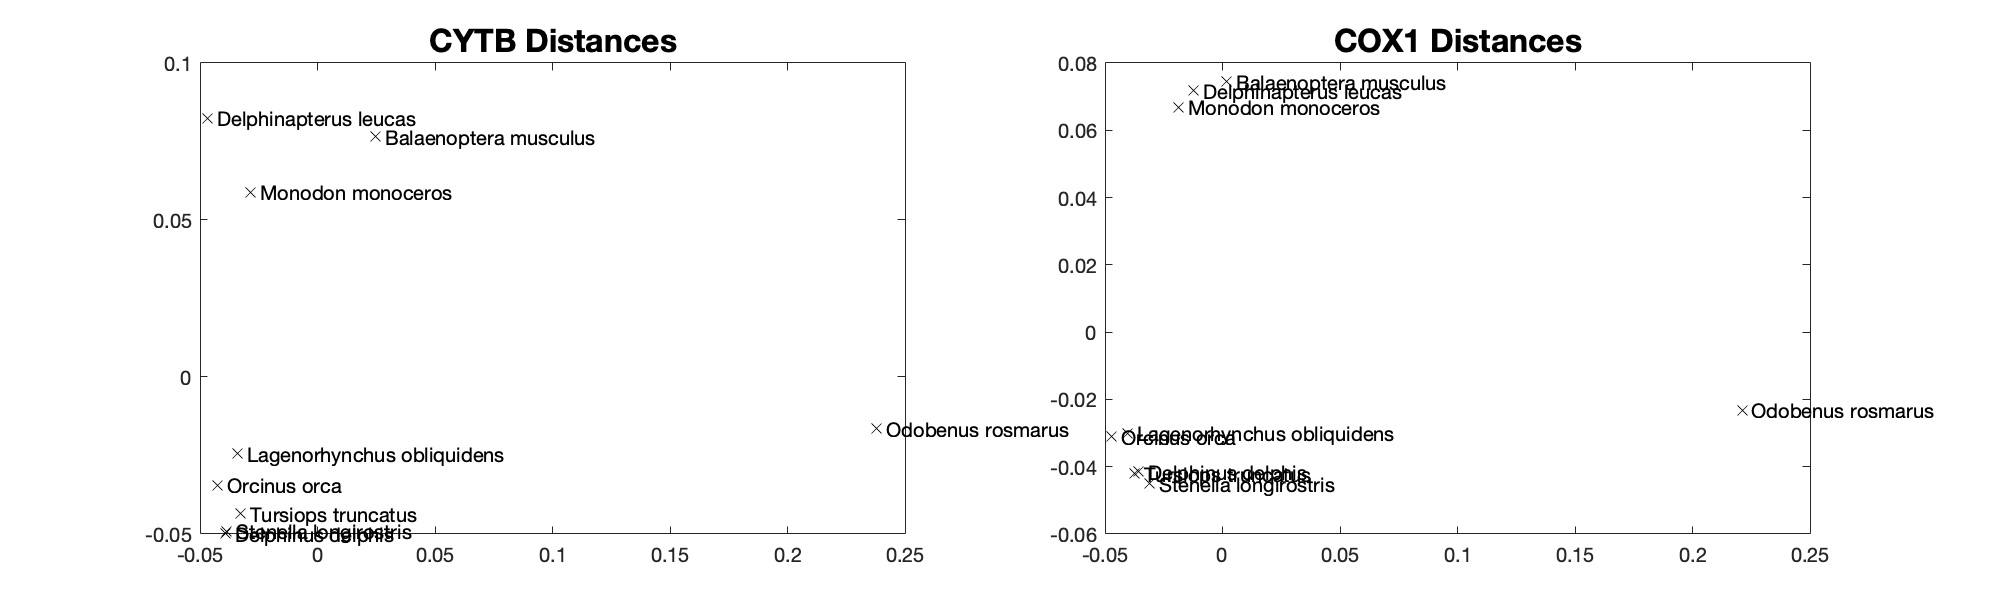

writetable(array2table(round(CYTB_NT_dist_matrix,4),'VariableNames',species_struct.Names),...
                       strcat(output_filename,'CYTB_dist_matrix.xls'));
writetable(array2table(round(COX1_NT_dist_matrix,4),'VariableNames',species_struct.Names),...
                       strcat(output_filename,'COX1_dist_matrix.xls'));

figure
tlo = tiledlayout(1,2);
set(gcf,'Units','points');
set(gcf,'position',[10, 10, 1000, 300] );

distance_matrices = {CYTB_NT_dist_matrix, COX1_NT_dist_matrix};
titles = {'CYTB Distances', 'COX1 Distances'};

for m = 1:2
    ax(m) = nexttile(tlo);
    
    points = cmdscale(distance_matrices{m});
    plot(ax(m), points(:,1),points(:,2), 'x', 'color', 'k')
    xlimits=get(ax(m),'xlim');
    text(ax(m), points(:,1) + (xlimits(2)-xlimits(1))/75, points(:,2), species_struct.Names)
    title(ax(m), titles{m}, 'FontSize', 16)
end

# Task 5

% tree for NT CYTB
tree_CYTB_NT = seqneighjoin(CYTB_NT_dist_matrix, 'equivar',species_struct.Names);
tree_CYTB_NT = reroot(tree_CYTB_NT, outgroup_num);

% tree for NT COX1
tree_COX1_NT = seqneighjoin(COX1_NT_dist_matrix, 'equivar',species_struct.Names);
tree_COX1_NT = reroot(tree_COX1_NT, outgroup_num);

% tree for AA CYTB
CYTB_AA_dist_matrix = squareform(seqpdist(species_struct.CYTB_AA, 'method',...
                              'jukes-cantor'));
tree_CYTB_AA = seqneighjoin(CYTB_AA_dist_matrix, 'equivar',species_struct.Names);
tree_CYTB_AA = reroot(tree_CYTB_AA, outgroup_num);

% tree for AA COX1
COX1_AA_dist_matrix = squareform(seqpdist(species_struct.COX1_AA, 'method',...
                              'jukes-cantor'));
tree_COX1_AA = seqneighjoin(COX1_AA_dist_matrix, 'equivar',species_struct.Names);
tree_COX1_AA = reroot(tree_COX1_AA, outgroup_num);

% concensus tree NT:
weights_NT = [sum(CYTB_NT_dist_matrix, 'all'), sum(COX1_NT_dist_matrix, 'all')];
weights_NT = weights_NT/sum(weights_NT);
consensus_NT_dist_matrix = weights_NT(1)*CYTB_NT_dist_matrix + weights_NT(2)*COX1_NT_dist_matrix;
tree_consensus_NT = seqneighjoin(consensus_NT_dist_matrix, 'equivar',species_struct.Names);
tree_consensus_NT = reroot(tree_consensus_NT, outgroup_num);

% concensus tree AA:
weights_AA = [sum(CYTB_AA_dist_matrix, 'all'), sum(COX1_AA_dist_matrix, 'all')];
weights_AA = weights_AA/sum(weights_AA);
consensus_AA_dist_matrix = weights_AA(1)*CYTB_AA_dist_matrix + weights_AA(2)*COX1_AA_dist_matrix;
tree_consensus_AA = seqneighjoin(consensus_AA_dist_matrix, 'equivar',species_struct.Names);
tree_consensus_AA = reroot(tree_consensus_AA, outgroup_num);

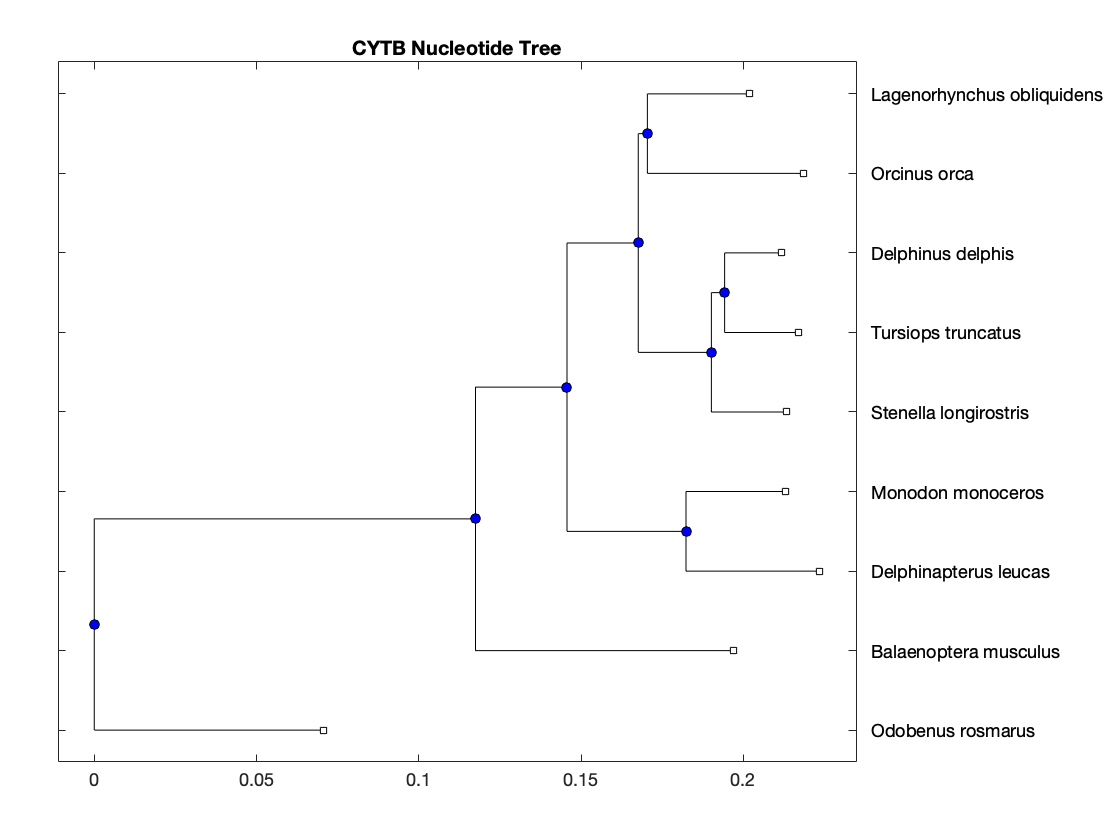

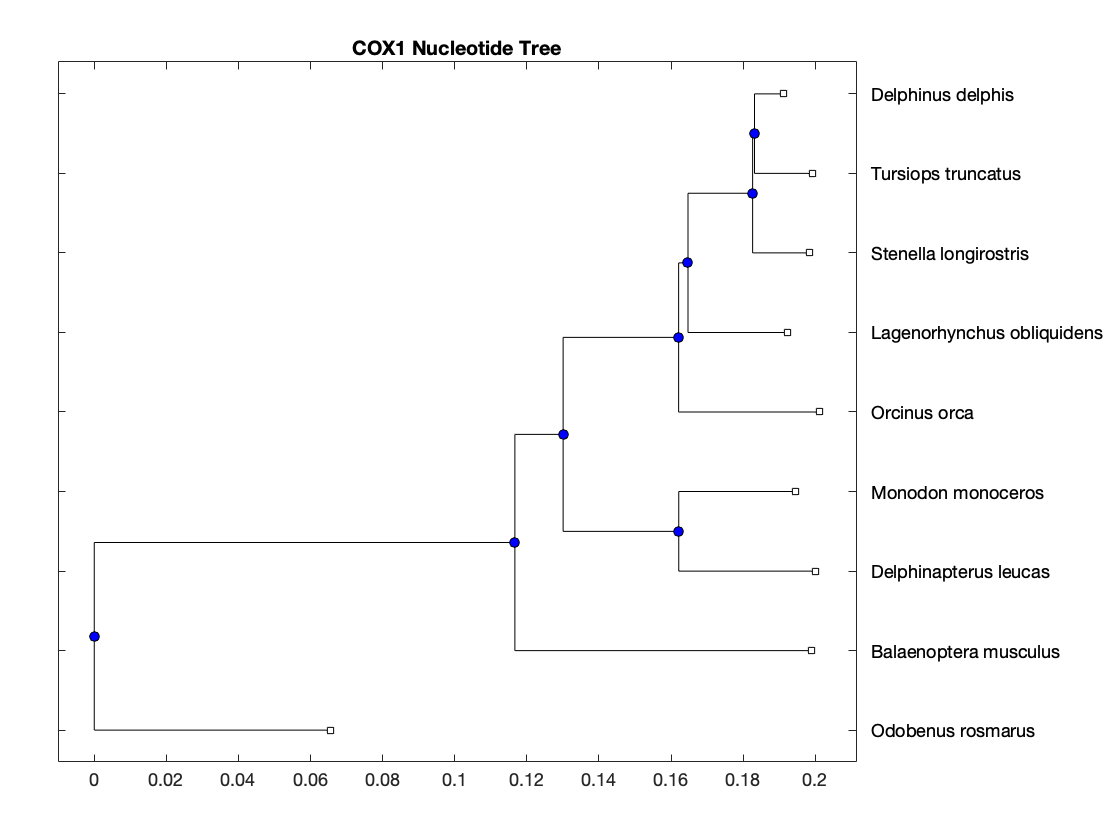

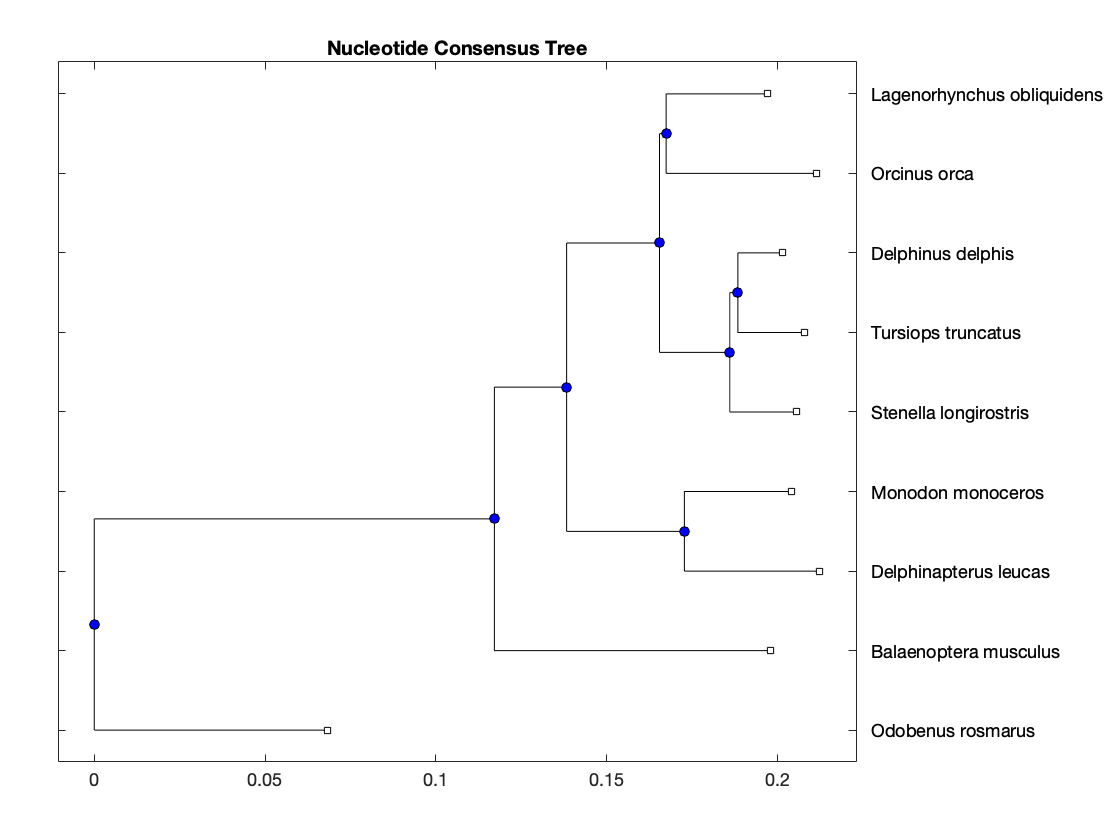

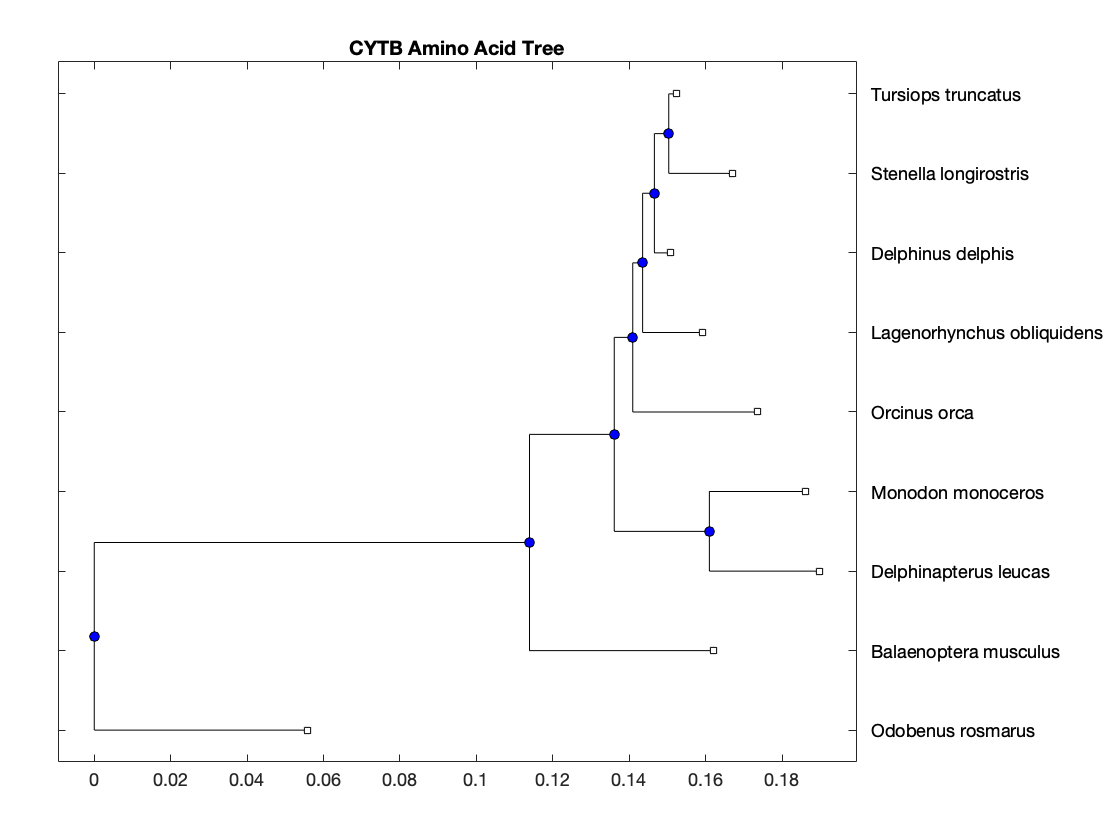

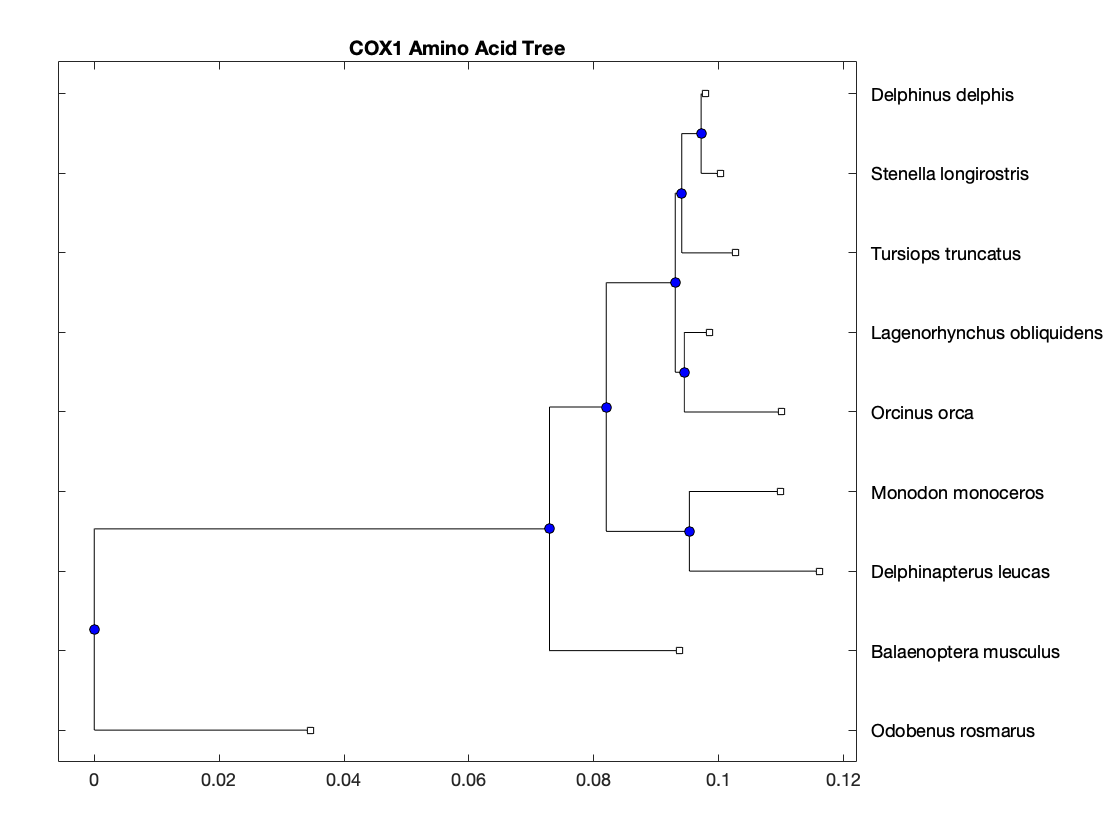

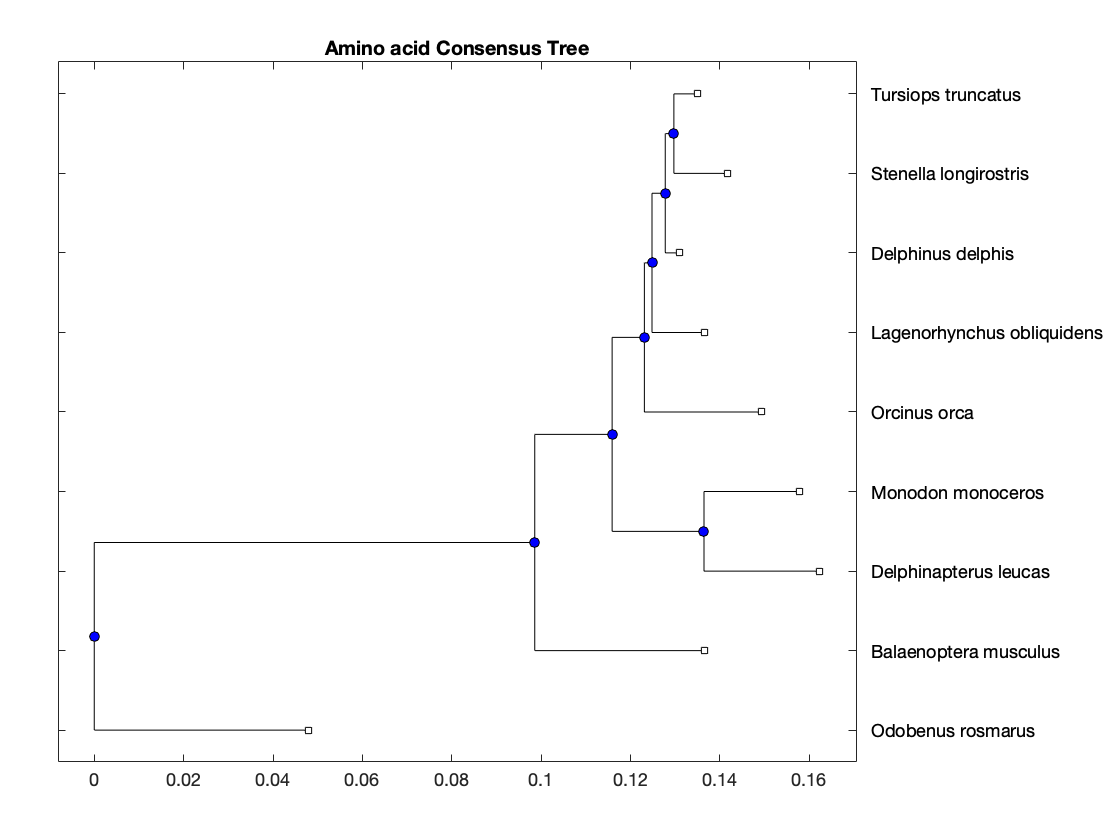

trees = {tree_CYTB_NT, tree_COX1_NT, tree_consensus_NT, tree_CYTB_AA, tree_COX1_AA, tree_consensus_AA};
tree_titles = {'CYTB Nucleotide Tree', 'COX1 Nucleotide Tree', 'Nucleotide Consensus Tree',...
               'CYTB Amino Acid Tree', 'COX1 Amino Acid Tree', 'Amino acid Consensus Tree'};

for t = 1:6
    figure;
    plot(trees{t});
    title(tree_titles{t});
end

# Task 7

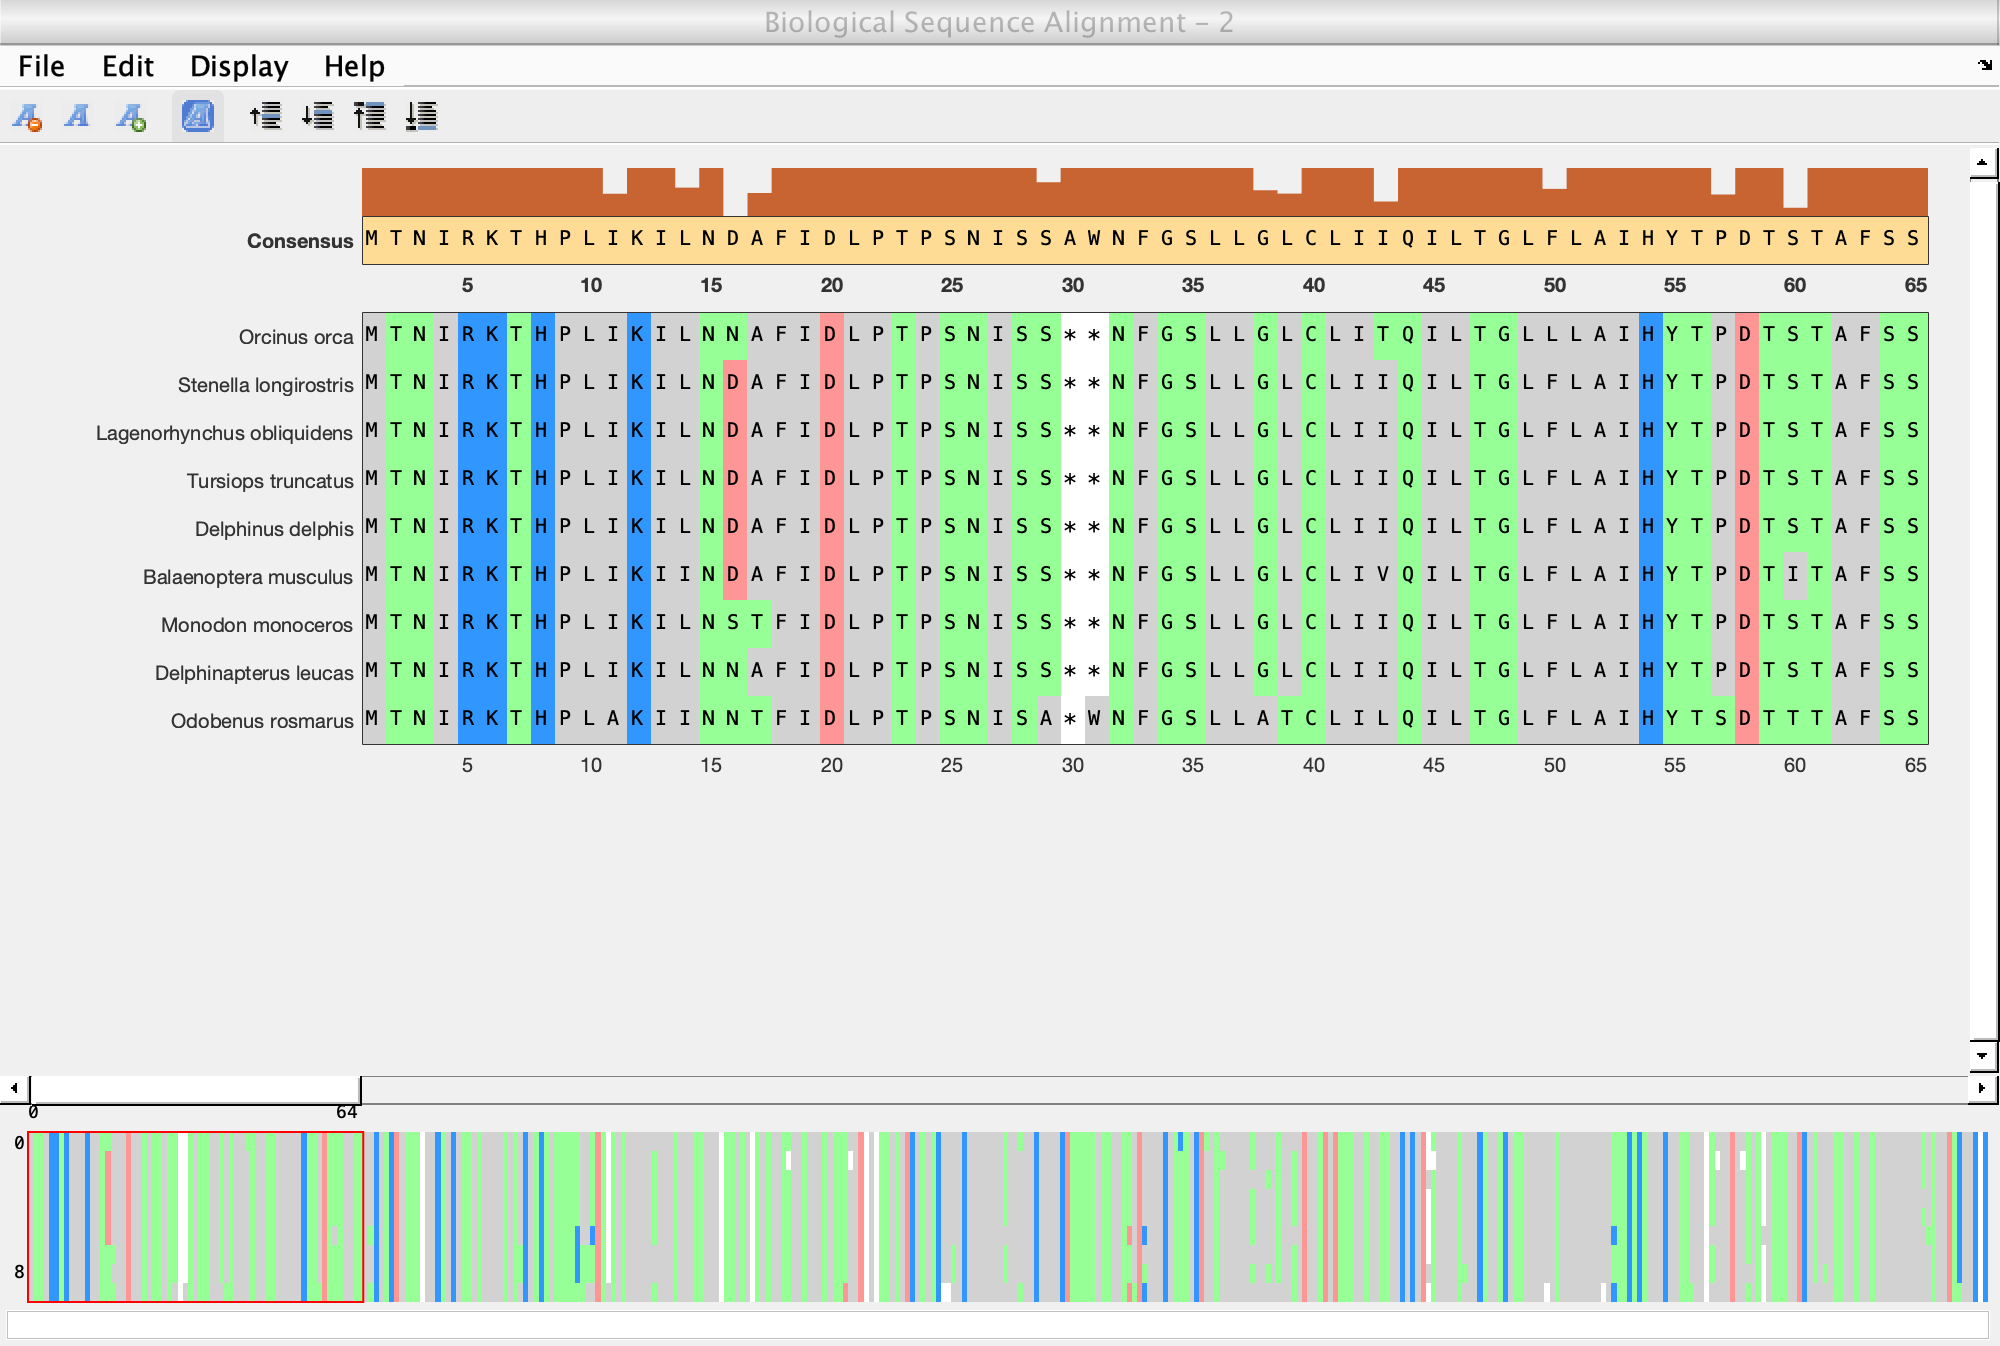

for s = 1:n_species
    CYTB_struct_vector(s) = struct('Sequence',species_struct.CYTB_AA{s},...
        'Header',species_struct.Names{s});
    COX1_struct_vector(s) = struct('Sequence',species_struct.COX1_AA{s},...
        'Header',species_struct.Names{s});
end
ma_CYTB = multialign(CYTB_struct_vector, tree_CYTB_AA);
seqalignviewer(ma_CYTB, 'alphabet','AA');

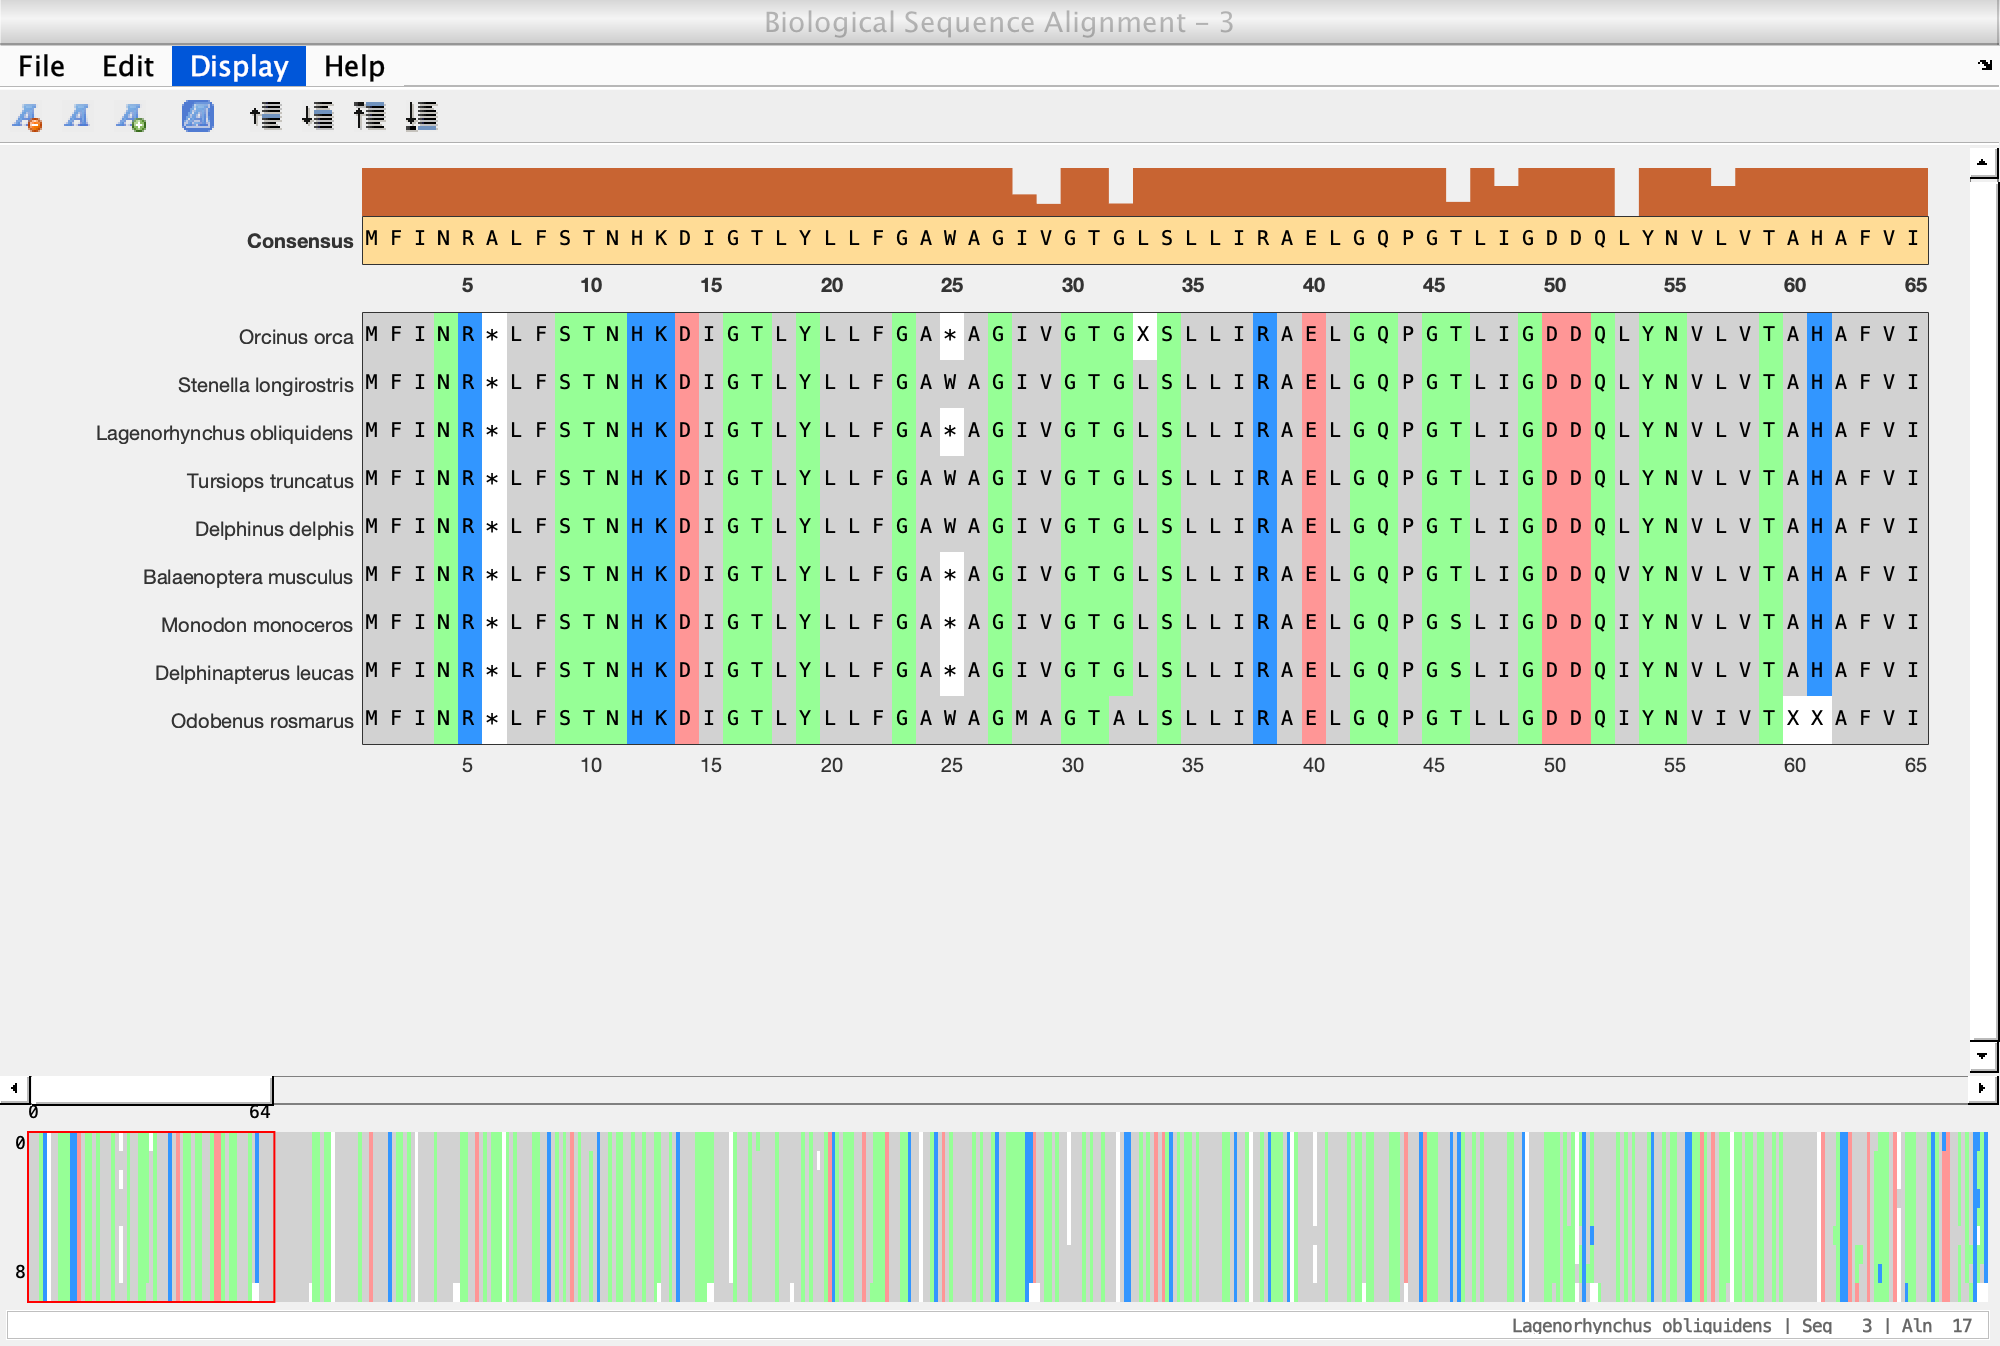

ans = 517

ans = 517

ans = 517

ans = 517

ans = 517

ans = 517

ans = 517

ans = 517

ans = 515

ma_COX1 = multialign(COX1_struct_vector, tree_COX1_AA);
seqalignviewer(ma_COX1, 'alphabet','AA');